Simon Andersen

sand22@student.aau.dk

Sound & Music Computing

# Pitch estimation

#### | *Signal Processing for Interactive Systems Mini Project*

*- Fundamental frequency estimation:*

- 'Automatic Transcription of Monophonic Music' project proposal

**NOTE: - THE PDF ADDED INCLUDES A MATLAB LIVE SCRIPT & PYTHON PROGRAM FILE THAT IS PART OF THE MAIN PROJECT !**

- **sand22_miniProject.pdf**

- **sand22_Matlab.zip**

- **sand22_Python.zip**

## Problem description

Calculating the fundamental frequency of a piano key by using auto-correlation as well as the YIN method for estimating and comparing the result to a neural network implementation.

## Fundamental frequency

The fundamental frequency is the scientific way of determining the pitch of a sound. Since different sounds signals include a vast spectrum of either harmonics or other frequencies the fundamental is known to be the lowest frequency that is present in a sound wave. This means the fundamental frequency of a sound is what is perceived by our ears. I.e. this is the mechanism that happens when sounds waves enters the human ear canal and from this we are able to differentiate between higher and lower frequencies. 

The fundamental frequency can be utilized in different areas of applications. One being speech recognition that is used to interact with virtual assistants like Siri and Google assistant. Here vowels and consonants are recognized as patterns to analyse the assignment made by the user. This allows hands-free help for mobile devices. Another use case can be music recognition which can be used by musicians to tune instruments or producers to get which key of a musical sample. 

Calculating the fundamental frequency of a sound wave can be done using mathematical techniques, which analyze the pattern of the sound wave over time to determine its underlying frequency.

## Estimation

To do fundamental frequency estimation it is important to understand the domain. First of all, in the act of calculating the fundamental frequency we deal with estimations. So the task is based on giving the most likely fundamenal frequency from the data that is being analysed. Which can be harder based on the characteristics of the given data. Also, sounds can be categorised as binary versions that describe the different types of sound signals. The two options being **periodic** and **non-periodic**.

- When a sound is determined as being periodic it means the sound have a repeating pattern of sound waves. In other words, that the waveform of the sound signal repeats itself after a fixed period of time. These sounds can be described by their *fundamental frequency*, which represents the rate at which the waveform repeats. Examples of periodic sounds include musical notes, sine waves, and the sound of a clock ticking.

- Now, non-periodic sounds is the opposite of **not **having a repeating pattern. These sounds can be characterized by their spectral content, which describes the distribution of frequencies present in the signal. Examples of non-periodic sounds include plosive sounds of speech, environmental noise, and the sound of a snare drum.

From this categorisation we're able to narrow the characteristics down to the periodic sounds when dealing with fundamental frequency estimation. The mathematical representation of a periodic signal is defined as:


$$x(n)=x(n-\tau)$$


This is referred as the period of the signal. To expand on this, we have the inverse of the period and this is the fundamental frequency of the periodic signal denoted as:

$f_0=\frac{1}{\tau}$,  [cycles / samples]

It is then shown that the fundamental frequency describes how many times the function $x(n)$ repeats itself pr. sample. Now, we know $\tau
$ is an unknown. So to be able to satisfy the periodicity of the signal, the estimation is about calculating the one that is the most satisfying to the claim. 

However, the field of fundamental frequency estimation has been explored by others before and different mathematical techniques already exists.

## Techniques

To chose the most efficient it is important to take the characteristics of the signal you are working with. Some of the explored techniques for this area is:

**Autocorrelation:**

Autocorrelation calculates the correlation of a signal with itself at different time lags. The fundamental frequency corresponds to the first peak in the autocorrelation function.

**Zero-crossing:**

Zero-crossing estimates the fundamental frequency by detecting the time intervals between consecutive zero crossings of the signal. This function may be unacurrate if used on signals that is not preprocessed enough or is a result of bad recordings. I.e. extensive noise or non-periodic components.

**Fourier transform:**

This method computes the spectrum of the signal and identifies the frequency component with the highest amplitude as the fundamental frequency. It is computationally efficient but might have a hard time estimating signals with more harmonics or which dynamic characteristcs.

**Cepstrum:**

The result of the cepstrum method is the analysis made by taking the Fourier transform of the logarithm of the power spectrum of a signal. Then taking the inverse Fourier transform to calculate the cepstrum. This identifies the peak in the cepstral domain and is deemed the fundamental frequency. On complex signals it can be computationally demanding.

Since we're dealing with the note of a piano our signal won't be that complex therefor many of these techniques would work. But using this for an monophonic music MIDI transcription program doing could work. Though analysing instruments would include many harmonics which could throw the autocorrelation of track. 

Though the noise in the signal will be minimal since I will be using a high end virtual instrument library as the data. Therefore any of these methods would be fine for calcualting the fundamental frequency, but in terms of computational efficiency it does not matter for this example.

## Analysis

### Waveform

In ableton I created a MIDI clip that I used to enter a C4 note with a piano library called "The Gentleman" from the plugin Kontakt 7.

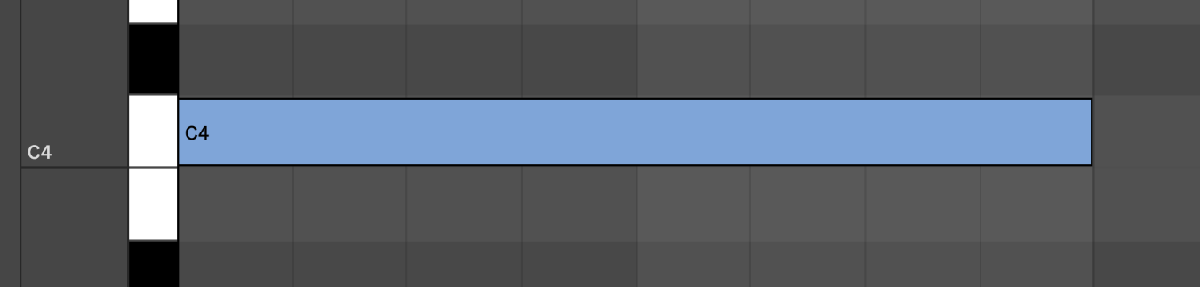

The fundamental frequency of the C4 of a piano sample is known to be around *261.6 Hz.*

f0 = 261.63;
disp(['Fundamental Frequency (f0): ', num2str(f0), ' Hz']);

Fundamental Frequency (f0): 261.63 Hz


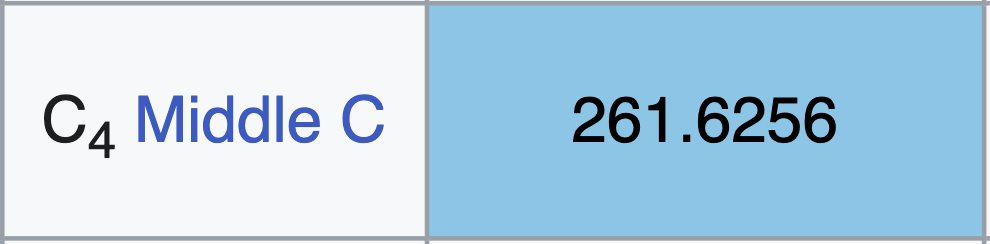

First of all we can visualise the waveform of the sample. This show the piano note with a decreasing amplitude.

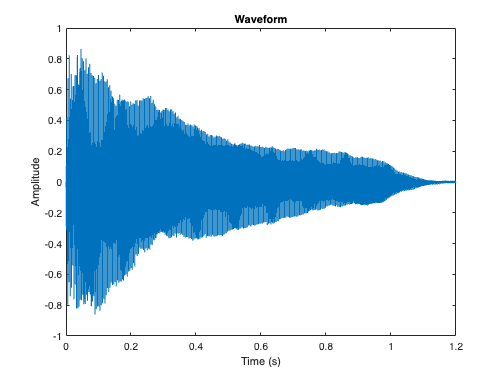

% Reading audio file
[audio, fs] = audioread("c4Piano.wav");

% Reducing to one channel
y = audio(:,1); 

% Calculate time vector
t = (0:length(y) - 1) / fs; 

% Plot waveform
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform');

xlim([0 1.2]);

By zooming into the data we can begin to notice the periodicity of the sound source. We are able to see the characteristics that is the repeating patterns and allows us to utilize the methods used for estimation of the fundamental frequency.

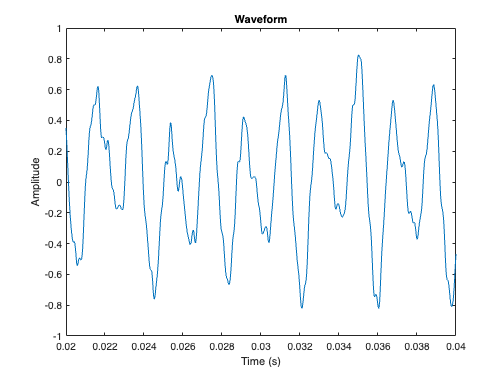

% Plot waveform
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform');

xlim([0.02 0.04]);

### Frequency spectrum

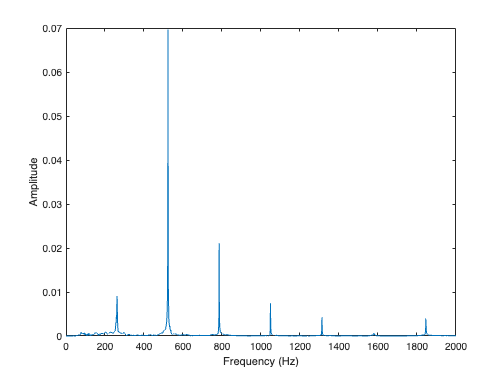

% Calculate FFT
N = length(y);
Y = fft(y);
P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(N/2))/N;

% Plot frequency spectrum
plot(f, P1);
xlabel('Frequency (Hz)');
ylabel('Amplitude');

xlim([0 2000])

For further analysis we can use the Fast Fourier Transform to visualise the frequency spectrum. This shows the amplitude of the frequencies that are that make up a sound or signal. From this we are able to determine the result of the fundamental frequency. 

Note that the fundamental frequency is not always the frequency with the highest amplitude. The fundamental frequency is defined as the lowest frequency component of a waveform, and it may or may not have the highest amplitude. In some cases, the harmonics or other frequency components may have higher amplitudes than the fundamental frequency which is what we are experiencing in this visualization. 

What becomes clear in this example is the recording almost only includes the harmonics of a note of a piano and does not have alot of unwanted frequencies that interfere the signal. From the previous standard of a piano key played at C4 it is shown that the lowest frequency component lies as around 260 Hz as expected.

### Spectrogram

*- Using spectogram() & pspectrum()*

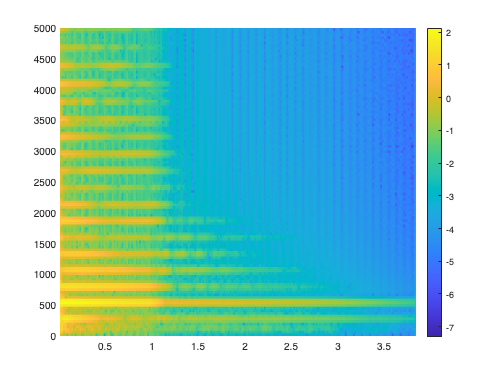

windowSize = 1024;

[S,F,T] = spectrogram(y, windowSize, windowSize/4,[],fs, 'yaxis');
pcolor(T,F,log10(abs(S))), shading flat, colorbar;
ylim([0 5000])

Another analysis tool in signal processing is the spectrogram, which essentially breaks down a visual representation of the frequencies and their respecitive amplitudes over time in an audio signal. This is graphed by the intensity of the sound represented by the color or brightness of each harmonic or overtone included in the recording when dealing with a note of a piano. From these visualisation we can deduce the result of the fundamental frequency of the recording must be around the 262 Hz.

## Implementation

### Autocorrelation

One of the aforementioned methods was autocorrelation. This is a technique used in statistics to extract information out of a dataset when dealing with time series. Since audio recording in the digital domain is a long list of data points this method translates well into signal processing. 

In it's basic form the autocorrelation function (ACF) measures the similarity between a signal and it's time-shifted version also called the *lagged version*. This means the method is comparing itself to itself at a different timeinterval in the signal. With this in mind we are able to estimate what frequency a signal is from this comparison by looking into the repeating patterns of the periodicity of the sound.

The autocorrelation equation of a signal $x(t)$ at lag $\tau$ is defined as:


$$\left(1\ldotp a\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{ACF}\left(\tau \right)=\int_{-\infty }^{\infty } x\left(t\right)\cdot x\left(t-\tau \right)\;\textrm{dt}$$


The equation tells it calculates the correlation between the signal $x(t)$

and its delayed version $x(t-\tau)$. The result is then the correlation of a signal with its past where a high autocorrelation value indicates that the signal has a strong periodic component with the given lag value.

When we want to use the autocorrelation function in practice with a discrete-time signal $x(n)$. This is given by:


$$\left(1\ldotp b\right)\;\;\;\;\;\;\;\textrm{ACF}\left(\tau \right)=\sum_{n=t+1}^{t+W-\tau } x\left(n\right)\cdot x\left(n+\tau \right)$$


$W$ is the number of samples in the signal and $\tau$ is the given lag value of the function.

A way of estimating the fundamental frequency using the autocorrelation function is by finding the period of the signal. The function will have peaks at integer multiples of the fundamental period that indicates the periodicity of the signal. The location of the first peak in the ACF will then represent the fundamental period which can be used to calculate the fundamental frequency. 

To estimate the fundamental frequency of a periodic signal, autocorrelation can be used to find the period of the signal. The ACF will have peaks of the fundamental period, indicating the periodicity of the signal. The location of the first peak in the ACF represents the fundamental period, which can be used to calculate the fundamental frequency.

Now, with the foundation of the method it should be known that not only is the ACF sensitive to noise but it can also produce false peaks due to the presence of harmonics and overtones. This means that the function can catch a different result than we would expect one of the harmonics in the signal interfere with the fundamental frequency. This is also know to have a sub-optimal time-frequency resolution.

The approch to implementing the functionality is then:

- Reading the signal

- Computing the ACF of the signal.

- Locating the first peak of the ACF that is not at a zero lag.

- Then calculating the fundamental frequency by dividing the sampling rate by the lag at the location of the first peak.

I tried to implement a working example for the ACF but got nothing to work on my own. So to get some working implementations for this project and not being stuck I tried to find other resources in order to come closer to an actual result. This was done by doing research through the Github Copilot, ChatCPT and implementations from Github as well as YouTube examples. 

### Example 1

Below is an example of a working implementation with reliance on build-in MatLab functionality. This is done by using the cross correlation function that creates a vector at different lags or time-series (1.2). To get the peaks for this it is then needed to retrieve the positive lags or time-series. This is because the negative lags generated by the xcorr function represent a time-reversed version of the signal that should be removed (1.2). With the vector cleaned by only having the positive lags we're able to use the build-in findpeaks() function as it returns the specific peaks and locations of these. This gives the location of the first peak, which is equivalent to the period of the fundamental frequency (1.3). Now we're able to calculate the fundamental frequency as said before by dividing the sampling rate with the lag at the location of the first peak (1.4).

The end result of this example gives the fundamental frequency of **518.8 Hz. **Which we from our initial analysis can deem as wrong.

% (1.1) Calculate autocorrelation using cross correlation
ACF = xcorr(y);

% (1.2) Cleaning the result by retrieving the positive lags
ACF = ACF(length(y):end);

% (1.3) Retrieve the location of the first peak in autocorrelation
[peaks, tau] = findpeaks(ACF);

% (1.4) Calculating the f0
f0 = fs / tau(1);

disp(['Fundamental Frequency (f0): ', num2str(f0), ' Hz']);

Fundamental Frequency (f0): 518.8235 Hz


### Example 2

For the next example that was generated used a time set time-series or lag that was calculated to do the auto-correlation (2.1). Now this was then used in running the discrete-time version of the $(1.b)$ equation on the lag window through a for loop and retrieving the positive lags (2.2). Then by using diff() in MatLab's build-in functionality the differences between adjacent elements are calculated. Then with the find() function the location of the first peak is found (2.4). At last doing the $f0$ calculation (2.5). The result gives the fundamental frequency of **1102.5 Hz **which we again can conclude as not correct. 

[y, fs] = audioread("c4Piano.wav");
y = audio(:,1); 

% (2.1) Set lag range as ms
lag = round(fs / 50); 

% (2.2) Calculate autocorrelation as well as retrieving the positve lags
ACF2 = zeros(1, lag);
for i = 1:lag
    ACF2(i) = sum(y(1:end-i+1) .* y(i:end));
end

% (2.3) Calculating the differences between adjacent elements
ACF_difference = diff(ACF2);

ans = 1×880 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0



% (2.4) Retrieve the location of the first peak in autocorrelation
[peak, tau2] = find(ACF_difference(1:end-1) .* ACF_difference(2:end) < 0, 1);

% (2.5) Calculating the f0
f0 = fs / tau2;

disp(['Fundamental frequency f(0): ' num2str(f0) ' Hz']);

Fundamental frequency f(0): 1075.6098 Hz


So from these small coding examples we are able to grasp some sort of gist in using autocorrelation as fundamental frequency estimation that might not always be the correct peak that the estimation calculates.

The reason for exploring the autocorrelation method was in order to lead into the implementation of the YIN algorithm that actually uses autocorrelation as a step in it's algorithm.

### YIN algorithm

The Yin algorithm is another method for doing fundamental frequency estimation. This is one of the more effective implementations of the estimation methods. The method includes 3 larger steps:

- **ACF:** Caluclating the autocorrelation function 

- **DF:** Computing the difference function of the signal that compare the differences between the the signal itsself and it's lagged version normalized by the lag value.

- **CMNDF:** Atlast, the algorithm goes through an process that computes the cumulative mean of the difference function that divides each element of the found difference. This step returns the normalized difference function that can be utilised to grant the location of the first minimum value, which in essential is the fundamental frequency of the signal.

The Yin algorithm is a widely used pitch detection method in various applications due to its robustness to noise and signal variations meaning i.e. a decreasing amplitude as we have in my recording. Alongside its computational efficiency. It may not be as accurate for signals that have dynamic characteristics where the pitch is attributed with vibrato or for signals with a wide spectrum of harmonics. Which might be a problem when working with instruments.

In essence, the Yin algorithm utilizes a difference function and iterative normalization process to approximate the fundamental frequency of an audio signal. The difference function is obtained by computing the difference between the audio signal and a delayed version of itself at various time lags. By locating the position of the minimum value in the resulting function, the fundamental frequency of the signal can be estimated.

The mathematical prowess that is used for this is first defined by the autocorrelation which was introduced already:


$$\left(2\ldotp a\right)\;\;\;\;\;\;\;\textrm{ACF}\left(\tau \right)=\sum_{n=t+1}^{t+W-\tau } x\left(n\right)\cdot x\left(n+\tau \right)$$


Then with the relationship of a periodic function with period T, and a invariant time shift of T, then squared and normalized gives:


$$\left(2\ldotp b\right)\;\;\;\;\;\;\;\textrm{ACF}\left(\tau \right)=\sum_{n=t+1}^{t+W-\tau } {\left(x\left(n\right)-x\left(n+\tau \right)\right)}^2$$


Then the difference function is known by:


$$\left(2\ldotp c\right)\;\;\;\;\;\;\;\textrm{DF}\left(\tau \right)=\sum_{n=t+1}^{t+W} {\left(x\left(n\right)-x\left(n+\tau \right)\right)}^2$$


Solving this equation reveals gives the product


$$\left(2\ldotp d\right)\;\;\;\;\;\;\;\textrm{DF}\left(\tau \right)=\sum_{n=t+1}^{t+W} \left({x\left(n\right)}^2 +{f\left(x+\tau \right)}^2 -2\cdot x\left(n\right)\cdot f\left(x+\tau \right)\right)$$


Which reveals the relationship expressed as the ACF:


$$\left(2\ldotp e\right)\;\;\;\;\;\;\;\textrm{DF}\left(\tau \right)=\textrm{ACF}\left(0,t\right)+\textrm{ACF}\left(0,t+\tau \right)-2\cdot \textrm{ACF}\left(\tau ,t\right)$$


The last step the Yin algorithm tackles is then the cumulative mean of the difference function which is defined as:


$$\left(2\ldotp f\right)\;\;\;\;\;\;\;\textrm{DF}\left(\tau \right)=\tau \cdot \frac{\textrm{DF}\left(\tau \right)}{\sum_{n=1}^{\tau } \textrm{DF}\left(n\right)}$$


The plan in implementing the Yin algorithm was inspired from the paper from the creators.

- Implement the the autocorrelation method (ACF)

- Implement the difference function (DF) and using the result of the ACF method in conjunction.

- Implement the cumulative mean of the squared difference function and using the implemented DF to create the average difference function.

- Identify the first point where the average difference function crosses a threshold because the autocorrelation is likely to choose a peak of higher order. Which is what we have experienced in the latter examples. The optimal threshold in the paper is stated as being 0.1

- (Dependant on the result of the ACF) Implement the parabolic interpolation step between two points on either side of the threshold to take into consideration that if the period is not a multiple of the sampling period. This is done to estimate the position of the minimum value in the squared difference function because .

- At last calculating the fundamental frequency to the estimated position of the minimum value in the squared difference function.

From these equations, implementations are able to be made. First defining a function for each step. With the references in my research i found an explanation of the Yin algorithm with some code to get you started in Python from this i wanted to expand on the implementation to be able to calculate the fundamental frequency of the recording of the piano key. From this i weren't able to expand on a working example for this though. But the Python code will be attached as an appendix in extra files. The example of the code is seen below.

### Example 3

#### Main method

`def` `main2``():`

    `sample_rate``, ``data` `=` `wavfile``.``read``(``"c4Piano.wav"``)`

    `data` `=` `data``.``astype``(``np``.``float64``)`

    `window_size` `=` `int``(``5` `/` `2000` `*` `44100``)`

    `bounds` `=`` [``20``, ``2000``]`

    `pitches` `=`` []`

    `for` `i` `in` `range``(``data``.``shape``[``0``] ``//`` (``window_size` `+` `3``)):`

        `pitches``.``append``(``detect_pitch6``(``data``, ``window_size``, ``i` `*` `window_size``, ``sample_rate``, ``bounds``))`

    `print``(``pitches``)`

#### `Defining functions`

`# - Autocorrelation function`

`def` `ACF``(``f``, ``W``, ``t``, ``lag``):`

    `return` `np``.``sum``(``f``[``t`` : ``t` `+` `W``] ``*` `f``[``t` `+` `lag`` : ``t` `+` `W` `+` `lag``])`

`# - Difference function of ACF`

`def` `DF``(``f``, ``W``, ``t``, ``lag``):`

    `return` `ACF``(``f``, ``W``, ``t``, ``0``) ``+` `ACF``(``f``, ``W``, ``t` `+` `lag``, ``0``) ``-`` (``2` `*` `ACF``(``f``, ``W``, ``t``, ``lag``))`

`# - Cumulative mean normalized difference function`

`def` `CMNDF``(``f``, ``W``, ``t``, ``lag``):`

    `# - Will only drop below 1 when the difference function is lower than the average of what we've guessed so far`

    `if` `lag` `==` `0``:`

        `return` `1`

    `return` `DF``(``f``, ``W``, ``t``, ``lag``) ``/` `np``.``sum``([``DF``(``f``, ``W``, ``t``, ``i` `+` `1``) ``for` `i` `in` `range``(``lag``)]) ``*` `lag`

### Pitch estimation using a neural network 

As a last point I wanted to make a comparison to see if using a neural network (NN) implementation would result in a more refined result or it would be totally off. To be put in perspective neural network applications is one of the most highlighted technical areas at the moment. Since we are dealing with a large amount of data in signals and using statistical methods this can be a great way of bridging the gap.

MatLab have a wide variety of build-in functions that are able to estimate fundamental frequency. The NN function is called *pitchnn(). *This function comes with a pretrained model based on the CREPE network which stand for Convolutional Representation for Pitch estimation.

[y, fs] = audioread("c4Piano.wav");
y = audio(:,1); 

First we can run the estimator with `ModelCapacity` set to `tiny` and `ConfidenceThreshold` disabled.

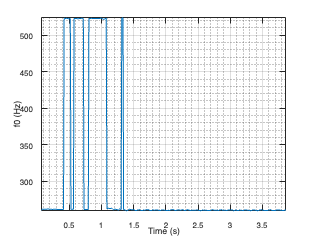

% Estimate pitch using pitch function
f0 = pitchnn(y, fs);

pitchnn(y, fs, 'ModelCapacity', 'tiny', 'ConfidenceThreshold', 0);

The documentation states that with the confidence thresholding disabled, `pitchnn() `provides a pitch estimate for every frame. 

Afterward the `ConfidenceThreshold` can be increaed to `0.8`.

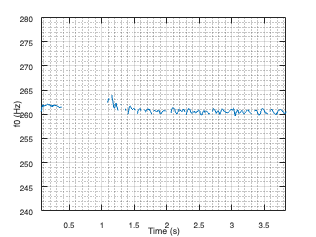

pitchnn(y, fs, 'ModelCapacity', 'tiny', 'ConfidenceThreshold', 0.8);

ylim([240 280])

At last the model should be run with the `ModelCapacity` set to `full`. As this normalizes the result as seen on the graphs.

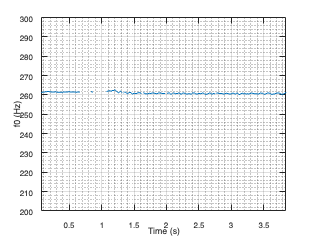

pitchnn(y,fs,'ModelCapacity','full','ConfidenceThreshold', 0.8);

f0_full = pitchnn(y,fs,'ModelCapacity','full','ConfidenceThreshold', 0.8);

ylim([200 300])

Then by running the spectrogram we are seeing a similar example as in the analysis.

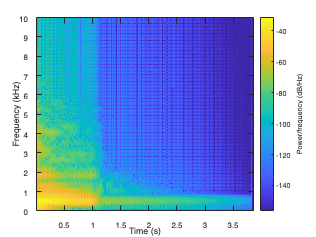

spectrogram(y, 250, 225, 4096, fs, 'yaxis');
ylim([0 10])

Nevertheless by taking the first entry of the estimation we can get a picture of what is found out:

% Printing the first estimation
disp(['Fundamental Frequency (f0): ', num2str(f0_full(1)), ' Hz']);

Fundamental Frequency (f0): 261.2717 Hz


The result lies at a 261.27 which comes really close to the actual result made from the inital analysis.

## Conclusion

The purpose of this project was to explore the field of pitch / fundamental frequency estimation. In this I wanted to work with the autocorrelation function as a tool to do the estimation. By research I found out that autocorrelation on it's own is not as viable of a method as it's precursor being the Yin algorithm. From this I wanted to do a simple autocorrelation example and then do the Yin example and at last compare with the build in neural network function. In doing the actual implementation I ran into a lot of hardships and kept being stuck on how to use MatLab. To handle the situation i tried going in to a Python implementation in order to see if the intuition would come a bit more natural. Now the actual runflow i have gotten to understand by my extensive research. Though putting the theory into an actual practical example I failed to. A lot of time was spent on doing an actual implementation and researching ways to go about it which is why the coding examples is unfinished. Then to get something up and running for the end of this project  I turned to other resources which is why i tried to generate the autocorrelation examples from ChatCPT and find other inspiration from other papers doing the implementation.

## Literature list

- [https://www.investopedia.com/terms/a/autocorrelation.asp#:~:text=Financial%20analysts%20and%20traders%20use,have%20on%20its%20future%20price.](https://www.investopedia.com/terms/a/autocorrelation.asp#:~:text=Financial%20analysts%20and%20traders%20use,have%20on%20its%20future%20price.)

- [https://www.physicsclassroom.com/class/sound/Lesson-4/Fundamental-Frequency-and-Harmonics](https://www.physicsclassroom.com/class/sound/Lesson-4/Fundamental-Frequency-and-Harmonics)

- [https://www.youtube.com/watch?v=Zt5Fip_ALM4](https://www.youtube.com/watch?v=Zt5Fip_ALM4)

- [https://www.youtube.com/watch?v=W585xR3bjLM](https://www.youtube.com/watch?v=W585xR3bjLM)

- [https://www.frontiersin.org/articles/10.3389/fnhum.2016.00274/full](https://www.frontiersin.org/articles/10.3389/fnhum.2016.00274/full)

- [https://www.johndcook.com/blog/2019/12/10/fundamental-frequency/](https://www.johndcook.com/blog/2019/12/10/fundamental-frequency/)

- [https://wiki.aalto.fi/pages/viewpage.action?pageId=149890776](https://wiki.aalto.fi/pages/viewpage.action?pageId=149890776)

- [http://smartdata.ece.ufl.edu/eee5502/2019_fall/lecture.html?lecture=02](http://smartdata.ece.ufl.edu/eee5502/2019_fall/lecture.html?lecture=02)

- [https://asmp-eurasipjournals.springeropen.com/articles/10.1186/s13636-016-0095-8](https://asmp-eurasipjournals.springeropen.com/articles/10.1186/s13636-016-0095-8)

- [https://aircconline.com/ijcseit/V7N1/7117ijcseit01.pdf](https://aircconline.com/ijcseit/V7N1/7117ijcseit01.pdf)

- [https://sail.usc.edu/~lgoldste/Ling582/Week%2011/auto.pdf](https://sail.usc.edu/~lgoldste/Ling582/Week%2011/auto.pdf)

- [https://academic.oup.com/gji/article/191/2/637/643572](https://academic.oup.com/gji/article/191/2/637/643572)

- [http://audition.ens.fr/adc/pdf/2002_JASA_YIN.pdf](http://audition.ens.fr/adc/pdf/2002_JASA_YIN.pdf)

- [https://arxiv.org/abs/1802.06182](https://arxiv.org/abs/1802.06182)

- [https://sound.eti.pg.gda.pl/student/eim/synteza/leszczyna/index_ang.htm](https://sound.eti.pg.gda.pl/student/eim/synteza/leszczyna/index_ang.htm)

- [https://www.stat.berkeley.edu/~bartlett/courses/153-fall2010/lectures/3.pdf](https://www.stat.berkeley.edu/~bartlett/courses/153-fall2010/lectures/3.pdf)

- [https://www.youtube.com/watch?v=W585xR3bjLM&t=3s](https://www.youtube.com/watch?v=W585xR3bjLM&t=3s)